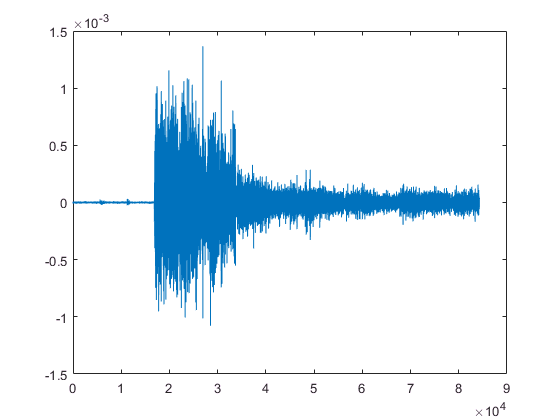

data = load('../../Data/20161231HandProdata.mat');
% size(data.ChannelsMovementsCell{1, 1}), 1x16857
% size(data.ChannelsMovementsCell{1, 2})
% size(data.ChannelsMovementsCell{1, 3})
% size(data.ChannelsMovementsCell{1, 4})
% size(data.ChannelsMovementsCell{1, 5})

ch = 1;
 rawdata = [...
            data.ChannelsMovementsCell{ch, 1}, ...
            data.ChannelsMovementsCell{ch, 2}, ...
            data.ChannelsMovementsCell{ch, 3}, ...
            data.ChannelsMovementsCell{ch, 4}, ...
            data.ChannelsMovementsCell{ch, 5} ...
            ];

% size(rawdata)         
figure;
plot(rawdata);

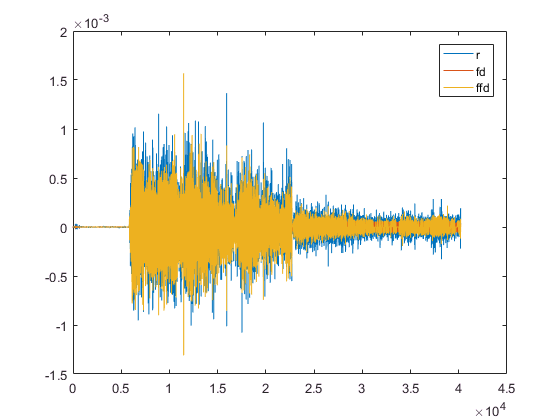

[fd, threshold, ffd] = ThreshFiltered(rawdata, 0.7);
figure;
startP = 11000;
endP = 51200;
plot(rawdata(1, startP:endP));hold on;
plot(fd(1, startP:endP)); hold on;
plot(ffd(1, startP:endP)); hold on;
legend({'r', 'fd', 'ffd'});

[restList, SpikesX, SpikesY] = SpikesDetection(ffd, 5);

size(SpikesY)

ans =         6979          11


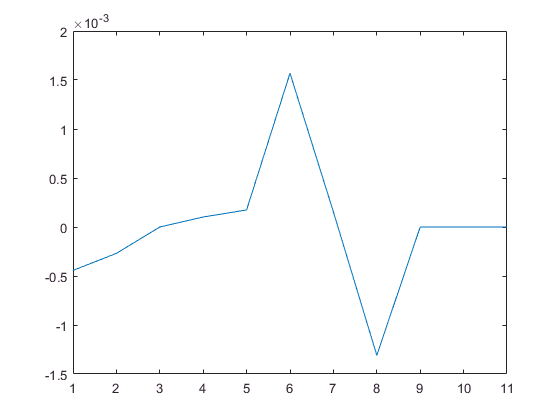

figure;
plot(SpikesY(1, :));

对波形进行无监督聚类

n_c = 10;
[idx, center, distance_within] = kmeans(SpikesY, n_c);

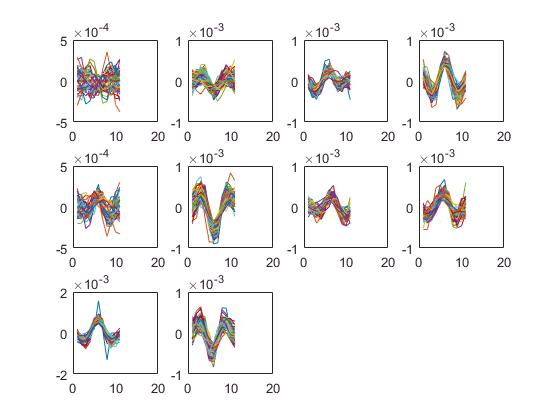

figure;
for m=1:n_c
    subplot(3,4,m);
    class_label{m} = SpikesY(idx==m, :);
    for s=1:size(class_label{m}, 1)
        plot(class_label{m}(s, :));hold on;
    end
end

由同一个类别的所有波形重新组成一个完整的通道数据，也就是从最初的单通道分解成10通道。

size(idx), size(SpikesX), size(SpikesY), size(ffd)

ans =         6979           1


ans =         6979          11


ans =         6979          11


ans =            1       84282


reList = ReconstructList(ffd, SpikesX, idx);
size(reList)

ans =           10       84282


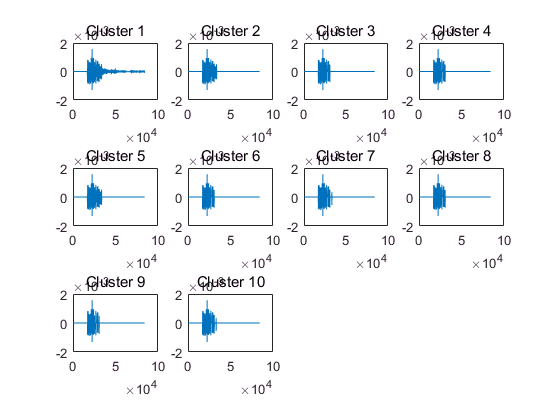

figure;
for i=1:10;
    subplot(3,4,i);plot(reList(i, :));
    title(['Cluster ', num2str(i)]);
end

按照常规方法，基于分解后的十通道数据进行：

    0. 数据分割；every movement section-16857

    1. 特征提取；

    2. 降维与分类；

0. 数据分割， Rawdata{nMV}, every element stands a label-sample matrix with nCh x L

Rawdata = cell(1, 5);
secL = 16857; % the length of every section
Rawdata{1} = reList(:, 1:secL);
Rawdata{2} = reList(:, secL+1:2*secL);
Rawdata{3} = reList(:, 2*secL+1:3*secL);
Rawdata{4} = reList(:, 3*secL+1:4*secL);
Rawdata{5} = reList(:, 4*secL+1:end);

addpath('../FeaturesExtraction');
fE.featuresCell = {'RMS', 'MAV', 'WL'};
fE.LW = 512;
fE.LI = 128;
sampleX = RawdataCell2SampleCellN(Rawdata, fE);
size(sampleX)

ans =      1     5


size(sampleX{2})

ans =    128    30


addpath('../DimensionReduction');
lda = LDA(6);
lda.SimpleTrainM(sampleX);
nRow = lda.Judge(sampleX{5}(1:20, :))

nRow =      1     5     5     5     5     5     5     5     3     5     3     5     5     5     5     5     5     5     5     5
